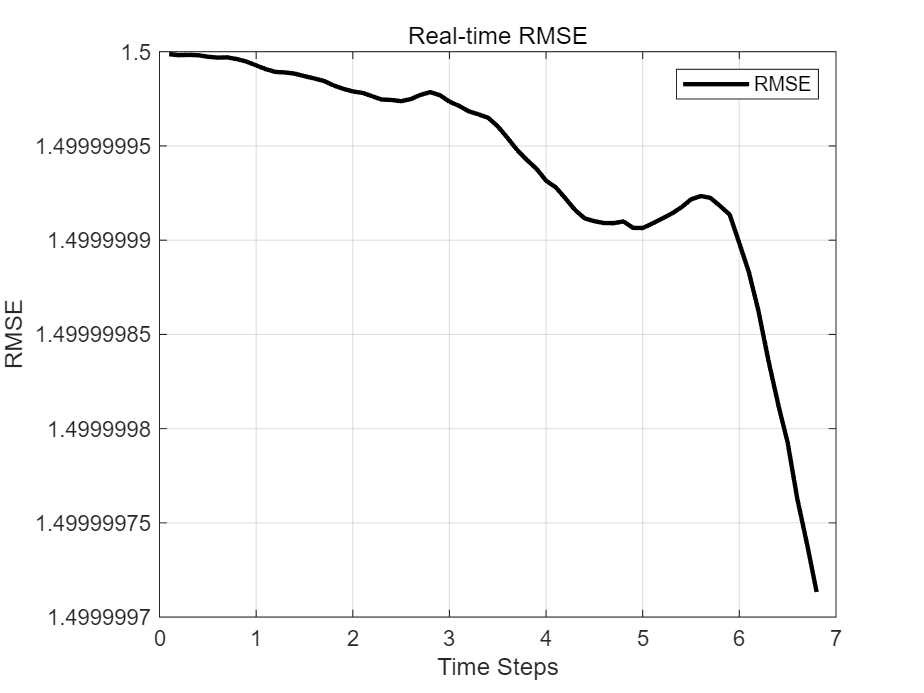

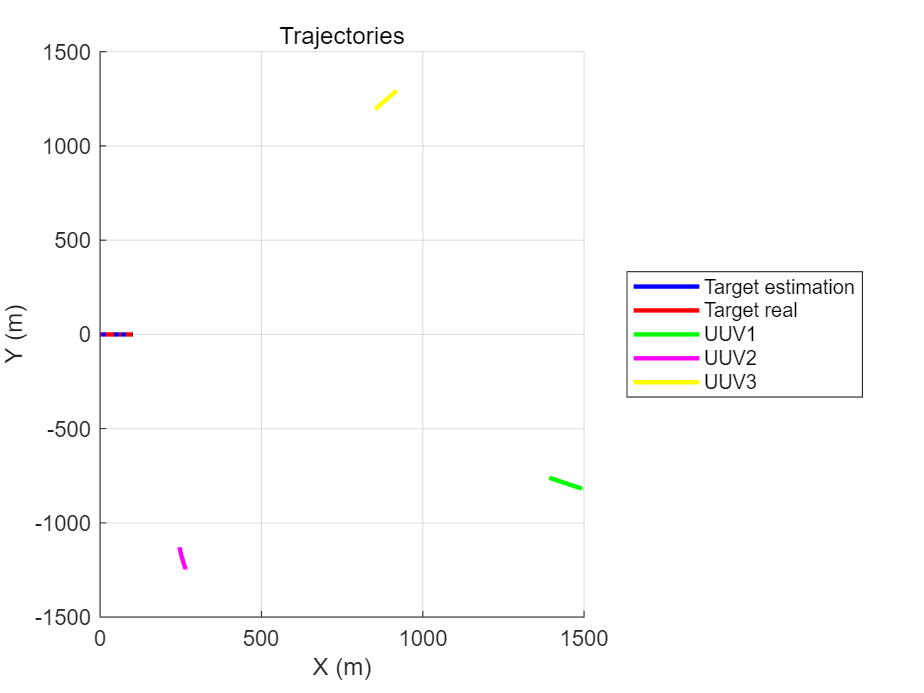

CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


CDN is NAN


2,번째 근접어뢰


clc;clear;close all;
%% Simulation Setting

time = 480; %total simulation time = 8*60 s
dt=0.1; % sampling time = 0.1 s
error = zeros();
%% Create Model
% 타겟 제원
% 속도 : 7 knot = 3.60111 m/s| 크기 : 6*6*60 (m^3) 
% 어뢰 제원
% 속도 : 35 knot = 18.0056 m/s | 크기 : - (m^3) | 배터리 시간 : 8분 = 480 초

% 타겟 생성
Target = createUUV([[0 0 0], [15, 0, 0]], [0 0]);

% UUV들의 초기 위치를 타겟 기준으로 2000m 이내에서 랜덤하게 생성
num_UUV = 3; % UUV의 개수
distance_threshold = 2000; % 거리 임계값

UUVs = cell(1, num_UUV); % UUV를 저장할 셀 배열
for i = 1:num_UUV
    % 2D 원 내부 랜덤 배치
    theta = 2 * pi * rand;                 % (0 ~ 2*pi)
    r = distance_threshold * sqrt(rand);    % (0 ~ distance_threshold)

    % X, Y 좌표 (원 내부)
    x = r * cos(theta) + Target.Pose(1);
    y = r * sin(theta) + Target.Pose(2);

    % Z 좌표는 0으로 고정
    z = 0;

    % UUV 생성 (초기 속도 [18,0,0] 은 임의)
    UUVs{i} = createUUV([[x, y, z], [18, 0, 0]], [0, 0]);

    % UUV 헤딩 설정
    UUVs{i} = generateTrackerHeading(Target, UUVs{i});

    %초기 유도 방향 설정
    UUVs{i} = guidedMotion1(Target.InitialState(1:6), UUVs{i},dt,30);

end


% UUV 변수에 할당
UUV1 = UUVs{1};
UUV2 = UUVs{2};
UUV3 = UUVs{3};

th = 30; % threshold for combining
curvecnt=0;

%% Recording 
Esti_Target_pos = zeros(time,6);
UUV1_pos = zeros(time/dt,3);
UUV2_pos = zeros(time/dt,3);
UUV3_pos = zeros(time/dt,3);
Target_pos = zeros(time/dt,3);
%% EKF Setting
Esti_P = eye(6); % 오차 공분산 행렬
Q = eye(6); % 시스템 잡음 공분산 행렬
Esti_X = Target.InitialState';

%% Simulate

% RMSE 그래프 설정
figure;
h_rmse = plot(NaN, NaN, 'k-', 'DisplayName', 'RMSE', 'LineWidth', 2);
hold on;
xlabel('Time Steps');
ylabel('RMSE');
title('Real-time RMSE');
grid on;
legend('Location', 'northeast');

% RMSE 데이터를 저장할 변수
rmse_values = [];
time_steps = [];


% ERROR 그래프 설정
figure;
x_error = plot(NaN, NaN, 'k-', 'DisplayName', 'ERROR', 'LineWidth', 2);
y_error = plot(NaN, NaN, 'g-', 'DisplayName', 'ERROR', 'LineWidth', 2);
z_error = plot(NaN, NaN, 'b-', 'DisplayName', 'ERROR', 'LineWidth', 2);
hold on;
xlabel('Time Steps');
ylabel('X,Y,Z ERROR');
title('Real-time ERROR');
grid on;
legend('Location', 'northeast');

% RMSE 데이터를 저장할 변수
error_values = [];
time_steps = [];

figure;
hold on;
grid on;

% 초기 플롯 설정
h_target_est = plot3(NaN, NaN, NaN, 'b-','DisplayName', 'Target estimation','LineWidth',2); % 추정 궤적
h_target_real = plot3(NaN, NaN, NaN, 'r-', 'DisplayName', 'Target real','LineWidth',2);      % 실제 타겟 궤적
h_uuv1 = plot3(NaN, NaN, NaN, 'g-', 'DisplayName', 'UUV1','LineWidth',2);                    % UUV1 궤적
h_uuv2 = plot3(NaN, NaN, NaN, 'm-', 'DisplayName', 'UUV2','LineWidth',2);                    % UUV2 궤적
h_uuv3 = plot3(NaN, NaN, NaN, 'y-', 'DisplayName', 'UUV3','LineWidth',2);                    % UUV3 궤적

title("Trajectories");
xlabel("X (m)");
ylabel("Y (m)");
zlabel("Z (m)");
legend('Location','eastoutside');
for i = 1:time/dt
    
    UUV1_pos(i, :) = UUV1.Pose;
    UUV2_pos(i, :) = UUV2.Pose;
    UUV3_pos(i, :) = UUV3.Pose;

    %extract uncertainarea of sonar sensors
    [uncertainArea,condNum] = findUncertaintyArea(UUV1, UUV2, UUV3, th);
    condition(i)=condNum;
    
     % if i==1
     %     initialUA=uncertainArea;
     %     numPoints = length(uncertainArea);
     %     idx1 = randi(numPoints);
     %     Esti_X(1:3)=uncertainArea(idx1,:);
     % end

    Target_pos(i, :) = Target.Pose;
    sigma = deg2rad(1)*condNum;
    R = eye(6) *(sigma^2);
    [Esti_X, Esti_P] = EKF(Esti_X, Esti_P, Q, R, Target.Pose(1:3)', UUV1.Pose(1:3)', UUV2.Pose(1:3)', UUV3.Pose(1:3)',dt);
    Esti_Target_pos(i, :) = Esti_X;
    rmse_values = update_rmse(Target_pos, Esti_Target_pos(1:i, 1:3), i, rmse_values, dt, h_rmse);
    % 최근접 어뢰 추출
    [direction_to_closest, idx] = calculate_direction_to_closest(Target.Pose, UUV1.Pose, UUV2.Pose, UUV3.Pose);

    % 회피 거리 임계값
    threshold_distance = 500;

    % 공격 거리 임계값
    threshold_attack_distance = 42;

     fprintf('%d,번째 근접어뢰\n',idx);
    if norm(direction_to_closest) < threshold_distance
        disp('**************************************************');
    end

    if norm(direction_to_closest) < threshold_attack_distance 
         fprintf('%d/4800번째 격추한 어뢰 %d 거리: %.2f m\n', i, idx, norm(direction_to_closest));
         disp("격추되었습니다");
        break; % 조건 충족 시 반복문 종료

    elseif norm(direction_to_closest) < threshold_distance && curvecnt < 1
        Target = calculate_new_heading(Target, direction_to_closest);
        curvecnt = curvecnt + 1;
    elseif norm(direction_to_closest) < threshold_distance && close_torpedo ~= idx
        Target = calculate_new_heading(Target, direction_to_closest);

    else 
        % Target = calculate_new_heading(Target, direction_to_closest);
    end
    close_torpedo = idx;

    % Target 및 UUV 업데이트
    Target = updateState(Target, Target.Velocity,dt);
    UUV1 = guidedMotion1(Esti_X, UUV1,dt,30);
    UUV1 = generateTrackerHeading(Target, UUV1);

    UUV2 = guidedMotion1(Esti_X, UUV2,dt,30);
    UUV2 = generateTrackerHeading(Target, UUV2);

    UUV3 = guidedMotion1(Esti_X, UUV3,dt,30);
    UUV3 = generateTrackerHeading(Target, UUV3);

    % 실시간 플롯 데이터 업데이트
    set(h_target_est, 'XData', Esti_Target_pos(1:i, 1), 'YData', Esti_Target_pos(1:i, 2), 'ZData', Esti_Target_pos(1:i, 3));
    set(h_target_real, 'XData', Target_pos(1:i, 1), 'YData', Target_pos(1:i, 2), 'ZData', Target_pos(1:i, 3));
    set(h_uuv1, 'XData', UUV1_pos(1:i, 1), 'YData', UUV1_pos(1:i, 2), 'ZData', UUV1_pos(1:i, 3));
    set(h_uuv2, 'XData', UUV2_pos(1:i, 1), 'YData', UUV2_pos(1:i, 2), 'ZData', UUV2_pos(1:i, 3));
    set(h_uuv3, 'XData', UUV3_pos(1:i, 1), 'YData', UUV3_pos(1:i, 2), 'ZData', UUV3_pos(1:i, 3));

    % 실시간 업데이트
    drawnow;

end